# Plot Fig S7

addpath(genpath('../../public_code'))

nstrain = 'male_before_timp_180511'; 
nNodes = 15; nDays = 10;

s3 = zeros(nNodes, 21600/2, nDays);
s2 = [];

for dayId = 0:nDays-1

    fn = ['etho_' nstrain '_12hr_dt2s_d' num2str(dayId) '.mat'];

    load(fn,'s');
    s = s';
    s = int64(s);
    s = remove_tunnel(s);

    s = s(:,1801:1800*7);
    s3(:, :, dayId+1) = s;
    
    s2 = [s2 s];
end

llh2 = zeros(3, nNodes, nDays);

for iday = 1:nDays
    s = s3(:,:,iday);

    fpday = ['sme_6h_nbs10_pseudocount_' nstrain '_iday' num2str(iday) '_full6hr.mat'];  
    load(fpday,'jij_gd_eachday','hir_gd_eachday')
    
    for imice = 1:nNodes
        llh_null = log(0.25); 
        llh2(1, imice, iday) = llh_null;
    
        m = mean(s(imice,:) == (1:4)',2);
        llh_indep = sum (log(m) .* m);
        llh2(2, imice, iday) = llh_indep;
        
        % compute_local_energy1.
        nStates = 4;
        jijMat = recoverUpt(jij_gd_eachday, nNodes);
        hirMat = reshape(hir_gd_eachday, nNodes, nStates-1);
        hirMat = [hirMat zeros(nNodes,1)];
        
        llh = 0; nSamples = size(s,2);
        for t = 1:nSamples
            mys = s(:, t);
            localE = compute_local_energy1(mys, imice, jijMat, hirMat);
            
            localE2 = zeros(1, nStates);
            mys_temp = mys;
            for istate = 1:nStates
                mys_temp(imice) = istate;
                localE2(istate) = compute_local_energy1(mys_temp, imice, jijMat, hirMat);
            end
            lh = exp(-localE) / sum(exp(-localE2));
            llh = llh + log(lh);
        end
        llh_pw = llh / nSamples;
        llh2(3, imice, iday) = llh_pw;
    end
end
llh2_bt = llh2; 


## Plot Fig S7 visualize conditional log-likelihood for each mouse

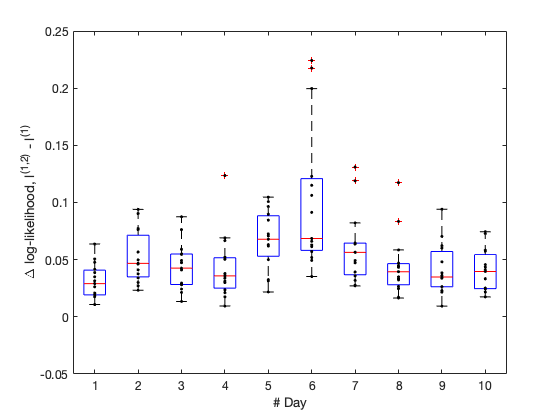


figure()
boxplot(squeeze(llh2_bt(3,:,:) - llh2_bt(2,:,:)))
hold on
plot(squeeze(llh2_bt(3,:,:) - llh2_bt(2,:,:))','k.')
hold off
set(gca,'fontsize',12)
xlabel('# Day')
ylabel('\Delta log-likelihood, l^{(1,2)} - l^{(1)}')
% title('Before TIMP')
ylim([-0.05 0.25])

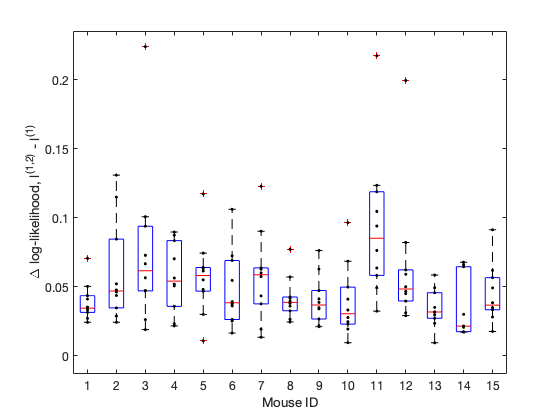

figure()
boxplot(squeeze(llh2_bt(3,:,:) - llh2_bt(2,:,:))')
hold on
plot(squeeze(llh2_bt(3,:,:) - llh2_bt(2,:,:)),'k.')
hold off
set(gca,'fontsize',12)
xlabel('Mouse ID')
ylabel('\Delta log-likelihood, l^{(1,2)} - l^{(1)}')